%Vehiculo
% salida yaw rate entrada steering
% El control está diseñado para considerar una velocidad lineal entre 4 y 20 m/s (circuito urbano)
%Regulador diseñado en continuo con H_inf más agresivo para modelo vehículo de Zhang
clear;
close all;

%System parameters
m=995;
a=1.233;
b=1.327;
Caf=41e3;
l=2.56;
Iz=1760;
Car=47e3;
g = 9.81;
%vx=6;
vx = ureal('vx',6,'Range',[4,20])

Uncertain real parameter "vx" with nominal value 6 and range [4,20].
Block Properties


a1=m*vx*a*Caf;
A1=m*a*Caf;
a2=l*Caf*Car;
A2=a2;
b1=m*vx*Iz;
B1=m*Iz;
b2=Iz*(Caf+Car)+m*((a^2)*Caf+(b^2)*Car);
B2=b2;
b3=(Caf*Car/vx)*(l^2)*(1+((m*vx*(b*Car-a*Caf))/(Caf*Caf*(l^2))));
B3=(Caf*Car)*(l^2)*(1+((m*vx*(b*Car-a*Caf))/(Caf*Caf*(l^2))));
s=tf('s');

pr=(a1*s+a2)/(b1*s^2+b2*s+b3);%Proceso Continuo con incertidumbre
pr.NominalValue


ans =
 
  A = 
               x1          x2          x3          x4          x5          x6          x7          x8
   x1           1           0           0           0           0           0           0           0
   x2           0           1           0           0           0           0           0          -1
   x3           0           0           1           0           0           0           0           0
   x4           0           0           0           1           0           0           0           0
   x5           0           0           0           0           1           0           0          -1
   x6           0           0           0           0           0           1           0           0
   x7           0           0           0           0           0           0           1  -1.638e+04
   x8           0           0   1.051e+07           0           0   1.826e+04           0   2.118e+09
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   0
   x5  

pr.Uncer

ans = struct with fields:
    vx: [1×1 ureal]


%analisis
Planta=tf(pr) %Planta nominal


Planta =
 
     28.72 s + 469.5
  ---------------------
  s^2 + 28.48 s + 201.6
 
Continuous-time transfer function.
Model Properties


tf(pr.NominalValue)


ans =
 
     28.72 s + 469.5
  ---------------------
  s^2 + 28.48 s + 201.6
 
Continuous-time transfer function.
Model Properties


disp('Polos:'),pole(Planta)

Polos:


ans =   -15.3275
  -13.1530


disp('Ceros:'),tzero(pr)

Ceros:


ans = -16.3456


%Perido de muestreo
T=10e-3%10ms

T = 0.0100

load('regmu_cochezhang')

%K: regulador continuo de orden 13
%Kred: regulador continu de orden 2
Kred=balred(K,2);

BC1=minreal(K*Planta/(1+K*Planta));

16 states removed.


BC2=minreal(Kred*Planta/(1+Kred*Planta));

5 states removed.


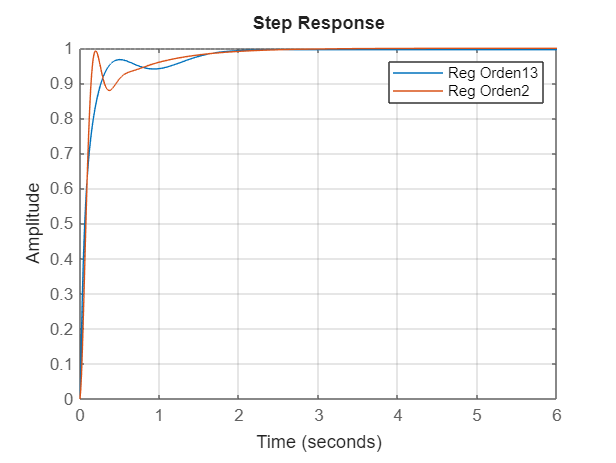

figure,step(BC1,BC2),legend('Reg Orden13','Reg Orden2'),grid


Gr=c2d(K,T,'zoh');
Reg=ss(Gr);
SR_Diag=canon(Reg,'modal')


SR_Diag =
 
  A = 
              x1        x2        x3        x4        x5        x6        x7        x8        x9       x10       x11       x12       x13
   x1     0.1002         0         0         0         0         0         0         0         0         0         0         0         0
   x2          0    0.6648    0.1448         0         0         0         0         0         0         0         0         0         0
   x3          0   -0.1448    0.6648         0         0         0         0         0         0         0         0         0         0
   x4          0         0         0    0.8009    0.1105         0         0         0         0         0         0         0         0
   x5          0         0         0   -0.1105    0.8009         0         0         0         0         0         0         0         0
   x6          0         0         0         0         0    0.9031   0.03557         0         0         0         0         0         0
   x7          0     

[pole(SR_Diag) abs(pole(SR_Diag))] %No Ordenados de rápido a lento

ans =    0.9839 + 0.0316i   0.9844 + 0.0000i
   0.9839 - 0.0316i   0.9844 + 0.0000i
   0.6648 + 0.1448i   0.6804 + 0.0000i
   0.6648 - 0.1448i   0.6804 + 0.0000i
   0.8009 + 0.1105i   0.8084 + 0.0000i
   0.8009 - 0.1105i   0.8084 + 0.0000i
   0.9031 + 0.0356i   0.9038 + 0.0000i
   0.9031 - 0.0356i   0.9038 + 0.0000i
   0.1002 + 0.0000i   0.1002 + 0.0000i
   0.9057 + 0.0000i   0.9057 + 0.0000i



%Ordenador polos de mayor a menor rapidez
[RegDiag_sep]=regdiagsep(SR_Diag, [1 2 2 2 1 1 1 2 1]);%separar todos los subespacios
S1=RegDiag_sep.S1;
p1=pole(S1)%p1=pole(SR_Diag.A(1,1))

p1 = 0.1002

S2=RegDiag_sep.S2;
p2p3=pole(S2)%=eig(SR_Diag.A(2:3,2:3))

p2p3 =    0.6648 + 0.1448i
   0.6648 - 0.1448i


S3=RegDiag_sep.S3;
p4p5=pole(S3)%p4p5=eig(SR_Diag.A(4:5,4:5))

p4p5 =    0.8009 + 0.1105i
   0.8009 - 0.1105i


S4=RegDiag_sep.S4;
p6p7=pole(S4)%p6p7=eig(SR_Diag.A(6:7,6:7))

p6p7 =    0.9031 + 0.0356i
   0.9031 - 0.0356i


S5=RegDiag_sep.S5;
p8=pole(S5)%p8=eig(SR_Diag.A(8,8))

p8 = 0.9057

S6=RegDiag_sep.S6;
p9=pole(S6)%p9p10=eig(SR_Diag.A(9:10,9:10))

p9 = 0.9657

S7=RegDiag_sep.S7;
p10=pole(S7)%p11=eig(SR_Diag.A(11,11))

p10 = 0.9723

S8=RegDiag_sep.S8;
p11p12=pole(S8)%p12=eig(SR_Diag.A(12,12))

p11p12 =    0.9839 + 0.0316i
   0.9839 - 0.0316i


S9=RegDiag_sep.S9;
p13=pole(S9)%p13=eig(SR_Diag.A(13,13))

p13 = 1.0000

%9 Dinámicas: 4 complejos + 5 reales

%Analisis de las 9 dinamicas
disp('[polo abs c*b ganancia]')

[polo abs c*b ganancia]


comp=[p1 abs(p1) norm(S1.C*S1.B) dcgain(S1)
 p2p3(1) abs(p2p3(1)) norm(S2.C*S2.B) dcgain(S2)
 p4p5(1) abs(p4p5(1)) norm(S3.C*S3.B(1,:)) dcgain(S3)
 p6p7(1) abs(p6p7(1)) norm(S4.C*S4.B(1,:)) dcgain(S4)
 p8 abs(p8) norm(S5.C*S5.B) dcgain(S5)
 p9 abs(p9) norm(S6.C*S6.B(1,:)) dcgain(S6)
 p10 abs(p10) norm(S7.C*S7.B) dcgain(S7)
 p11p12(1) abs(p11p12(1)) norm(S8.C*S8.B) dcgain(S8)
 p13 abs(p13) norm(S9.C*S9.B) dcgain(S9)]

comp = 1.0e+02 *

   0.0010 + 0.0000i   0.0010 + 0.0000i   0.0042 + 0.0000i   0.0046 + 0.0000i
   0.0066 + 0.0014i   0.0068 + 0.0000i   0.0000 + 0.0000i  -0.0001 + 0.0000i
   0.0080 + 0.0011i   0.0081 + 0.0000i   0.0001 + 0.0000i  -0.0003 + 0.0000i
   0.0090 + 0.0004i   0.0090 + 0.0000i   0.0000 + 0.0000i   0.0001 + 0.0000i
   0.0091 + 0.0000i   0.0091 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0097 + 0.0000i   0.0097 + 0.0000i   0.0000 + 0.0000i   0.0003 + 0.0000i
   0.0097 + 0.0000i   0.0097 + 0.0000i   0.0000 + 0.0000i   0.0004 + 0.0000i
   0.0098 + 0.0003i   0.0098 + 0.0000i   0.0001 + 0.0000i   0.0061 + 0.0000i
   0.0100 + 0.0000i   0.0100 + 0.0000i   0.0003 + 0.0000i   8.9236 + 0.0000i



%Ordenados por rapidez
%[p1 p2p3 p4p5 p6p7 p8 p9 p10 p11p12 p13]
%Ordenados por ganancia (c*b) residuo
%[p1 p13 p4p5 p11p12 p6p7 p10 p9 p2p3 p8]
%Ordenados por ganancia estática
%[p13 p11p12 p1 p10 p4p5 p9 p2p3 p6p7 p8]
%Analisis modelo balanceado
[SR_Bal gr]=balreal(Gr)


SR_Bal =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12         x13
   x1            1    0.000156  -0.0001831  -7.926e-06   7.356e-07  -3.142e-09   8.106e-07   1.457e-07   7.052e-09   5.868e-09   1.887e-08   1.055e-09  -9.864e-11
   x2     0.000156      0.7653      0.3846    -0.01711    -0.01202   9.514e-05    -0.01226    -0.00228  -0.0001102  -9.275e-05  -0.0002983  -1.666e-05   1.558e-06
   x3   -0.0001831      0.3846      0.3142     0.09362     0.03072   -0.000252     0.03113    0.005805   0.0002804   0.0002363   0.0007601   4.245e-05  -3.971e-06
   x4    7.926e-06     0.01711    -0.09362      0.9899   -0.005883   4.431e-05   -0.006049   -0.001121  -5.415e-05  -4.554e-05  -0.0001465  -8.181e-06   7.652e-07
   x5   -7.356e-07     0.01202    -0.03072   -0.005883      0.9028    -0.07437     -0.2279    -0.02104   -0.001059  -0.0006549   -0.002084  -0.0001191   1.108e-05
   

gr =   446.1896
    0.5678
    0.3704
    0.1933
    0.0027
    0.0025
    0.0009
    0.0001
    0.0001
    0.0000


disp('[polo gan]')

[polo gan]


[pole(SR_Bal) gr]

ans = 1.0e+02 *

   0.0010 + 0.0000i   4.4619 + 0.0000i
   0.0066 + 0.0014i   0.0057 + 0.0000i
   0.0066 - 0.0014i   0.0037 + 0.0000i
   0.0080 + 0.0011i   0.0019 + 0.0000i
   0.0080 - 0.0011i   0.0000 + 0.0000i
   0.0090 + 0.0004i   0.0000 + 0.0000i
   0.0090 - 0.0004i   0.0000 + 0.0000i
   0.0091 + 0.0000i   0.0000 + 0.0000i
   0.0100 + 0.0000i   0.0000 + 0.0000i
   0.0098 + 0.0003i   0.0000 + 0.0000i


%Ordenados por gr (gramiano)
%[p1 p2p3 p4p5 p6p7 p8 p13 p11p12 p10 p9]
 
 

%Prueba para N=6
%Hay muchos polos complejos que no se pueden separar en la forma diagonal
%Habra que cambiar el orden
%r=[p1][p2p3]
%l1=[p4p5]
%l2=[p6p7]
%l3=[p8][p9]
%l4=[p10]
%l5= [p11p12]
%l6=[p13]

N=6;
GrN6=d2d(Gr,T*N);%Discreto a periodo lento


nr=3;%1 real+2complej
nl=[2 2 2 1 2 1];%(2complej) + (2complej) + (2real) + (1real) + (2complej) + (1real)
%Reduce el orden de 15 a 5-4
[RegDiag_sep]=regdiagsep(SR_Diag, [nr nl]);%separar 10 subespacios
RegDiag_Rap=RegDiag_sep.S1;
RegDiag_Len1=RegDiag_sep.S2;
RegDiag_Len1_ext=d2d(RegDiag_Len1,N*T);
RegDiag_Len2=RegDiag_sep.S3;
RegDiag_Len2_ext=d2d(RegDiag_Len2,N*T);
RegDiag_Len3=RegDiag_sep.S4;
RegDiag_Len3_ext=d2d(RegDiag_Len3,N*T);
RegDiag_Len4=RegDiag_sep.S5;
RegDiag_Len4_ext=d2d(RegDiag_Len4,N*T);
RegDiag_Len5=RegDiag_sep.S6;
RegDiag_Len5_ext=d2d(RegDiag_Len5,N*T);
RegDiag_Len6=RegDiag_sep.S7;
RegDiag_Len6_ext=d2d(RegDiag_Len6,N*T);


%Forma balanceada
[RegBal_sep]=regsep(SR_Bal,[nr nl]);%[nr nl1 nl2 nl3 nl4 nl5 nl6]
RegBal_Rap=RegBal_sep.S1;
RegBal_Len1=RegBal_sep.S2;
RegBal_Len1_ext=d2d(RegBal_Len1,N*T);
RegBal_Len2=RegBal_sep.S3;
RegBal_Len2_ext=d2d(RegBal_Len2,N*T);
RegBal_Len3=RegBal_sep.S4;
RegBal_Len3_ext=d2d(RegBal_Len3,N*T);
RegBal_Len4=RegBal_sep.S5;
RegBal_Len4_ext=d2d(RegBal_Len4,N*T);
RegBal_Len5=RegBal_sep.S6;
RegBal_Len5_ext=d2d(RegBal_Len5,N*T);
RegBal_Len6=RegBal_sep.S7;
RegBal_Len6_ext=d2d(RegBal_Len6,N*T);


sim('PruebaN6');

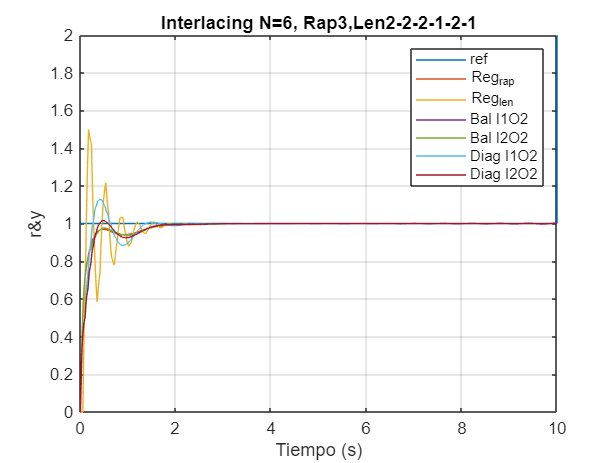

f=figure;
set(f,'Name','Interlacing N=6, Rap3,Len2-2-2-1-2-1')
plot(datos.time,datos.signals.values),ylabel('r&y'),xlabel('Tiempo (s)'),grid
title('Interlacing N=6, Rap3,Len2-2-2-1-2-1');
legend('ref','Reg_{rap}','Reg_{len}','Bal I1O2','Bal I2O2','Diag I1O2', 'Diag I2O2')

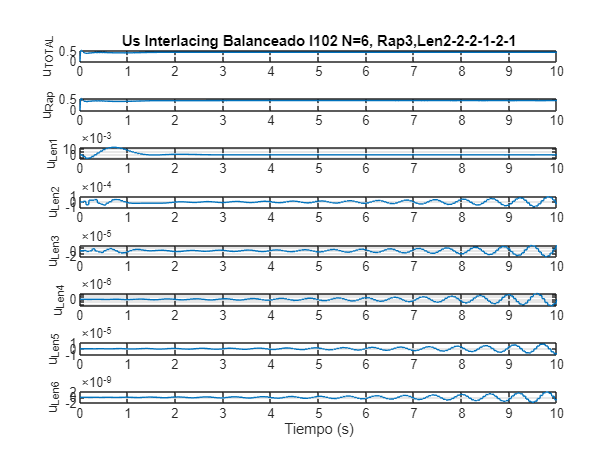

%Los modelos balanceados tieens mucha oscilación, casi tanta como el
%regulador lento. Pero los modelos diagonales funcioanan bastrante bien,
%sobre todo el I2O2
save('InterlacinN6.mat','datos');%Guardar datos para comparativa

f=figure;
set(f,'Name','U Interlacing Balanceado I102 N=6, Rap3,Len2-2-2-1-2-1')
subplot(8,1,1),plot(Us.time,Us.signals(1).values),ylabel('u_{TOTAL}'),grid
title('Us Interlacing Balanceado I102 N=6, Rap3,Len2-2-2-1-2-1');
subplot(8,1,2),plot(Us.time,Us.signals(2).values),ylabel('u_{Rap}'),grid;
subplot(8,1,3),plot(Us.time,Us.signals(3).values),ylabel('u_{Len1}'),grid;
subplot(8,1,4),plot(Us.time,Us.signals(4).values),ylabel('u_{Len2}'),grid;
subplot(8,1,5),plot(Us.time,Us.signals(5).values),ylabel('u_{Len3}'),grid;
subplot(8,1,6),plot(Us.time,Us.signals(6).values),ylabel('u_{Len4}'),grid;
subplot(8,1,7),plot(Us.time,Us.signals(7).values),ylabel('u_{Len5}'),grid;
subplot(8,1,8),plot(Us.time,Us.signals(8).values),ylabel('u_{Len6}'),grid;
xlabel('Tiempo (s)'),

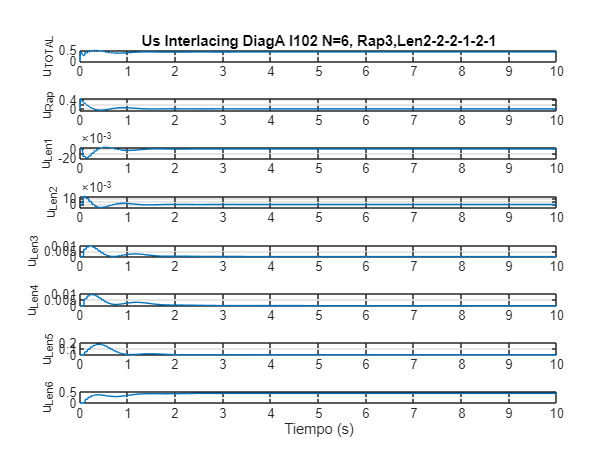


f=figure;
set(f,'Name','U Interlacing DiagA I102 N=6, Rap3,Len2-2-2-1-2-1')
subplot(8,1,1),plot(UsDiag.time,UsDiag.signals(1).values),ylabel('u_{TOTAL}'),grid;
title('Us Interlacing DiagA I102 N=6, Rap3,Len2-2-2-1-2-1');
subplot(8,1,2),plot(UsDiag.time,UsDiag.signals(2).values),ylabel('u_{Rap}'),grid;
subplot(8,1,3),plot(UsDiag.time,UsDiag.signals(3).values),ylabel('u_{Len1}'),grid;
subplot(8,1,4),plot(UsDiag.time,UsDiag.signals(4).values),ylabel('u_{Len2}'),grid;
subplot(8,1,5),plot(UsDiag.time,UsDiag.signals(5).values),ylabel('u_{Len3}'),grid;
subplot(8,1,6),plot(UsDiag.time,UsDiag.signals(6).values),ylabel('u_{Len4}'),grid;
subplot(8,1,7),plot(UsDiag.time,UsDiag.signals(7).values),ylabel('u_{Len5}'),grid;
subplot(8,1,8),plot(UsDiag.time,UsDiag.signals(8).values),ylabel('u_{Len6}'),grid;
xlabel('Tiempo (s)'),